theta10  = 0;
vtheta10 = 0;
atheta10 = 0;
theta1f  = -21.5727;
vtheta1f = 0;
atheta1f = 0;
theta30  = 0;
vtheta30 = 0;
atheta30 = 0;
theta3f  = 57.0064

theta3f = 57.0064

vtheta3f = 0

vtheta3f = 0

atheta3f = 0;
d40      = 0;
vd40     = 0;
ad40     = 0;
d4f      = 25.0674

d4f = 25.0674

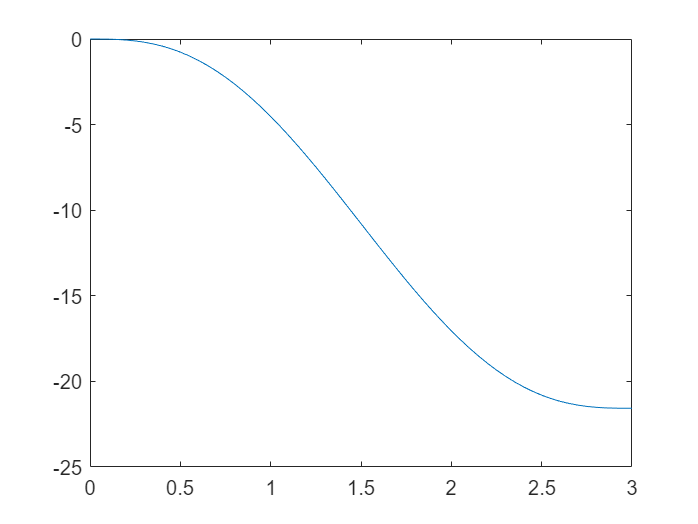

vd4f     = 0;
ad4f     = 0;
t0       = 0;
t1       = 3;
state1_t = [theta10; vtheta10; atheta10; theta1f; vtheta1f; atheta1f];
state3_t = [theta30; vtheta30; atheta30; theta3f; vtheta3f; atheta3f];
state4_t = [d40; vd40; ad40; d4f; vd4f; ad4f];

T = [ t0^5      t0^4      t0^3     t0^2    t0   1;
      5*t0^4    4*t0^3    3*t0^2   2*t0    1    0;
      20*t0^3   12*t0^2   6*t0     1       0    0;
      t1^5      t1^4      t1^3     t1^2    t1   1;
      5*t1^4    4*t1^3    3*t1^2   2*t1    1    0;
      20*t1^3   12*t1^2   6*t1     1       0    0];
A_theta1 = T\state1_t;
A_theta3 = T\state3_t;
A_d4     = T\state4_t;

t=(t0:0.05:t1)';
path=zeros(length(t),6);% theta1;vtheta1;atheta1; theta3;vtheta3;atheta3; d4;vd4;ad4
for i = 1:length(t)
    % theta1(degree) vtheta1(deg/sec) atheta1(deg/sec^2)
    path(i,1) = [t(i)^5,   t(i)^4,   t(i)^3,   t(i)^2, t(i), 1]*A_theta1;    
    path(i,2) = [5*t(i)^4, 4*t(i)^3, 3*t(i)^2, 2*t(i), 1,    0]*A_theta1;
    
    % theta3(degree) vtheta(deg/sec) atheta3(deg/sec^2)
    path(i,3) = [t(i)^5,   t(i)^4,   t(i)^3,   t(i)^2, t(i), 1]*A_theta3;
    path(i,4) = [5*t(i)^4, 4*t(i)^3, 3*t(i)^2, 2*t(i), 1,    0]*A_theta3;

    % d4(mm) vd4(mm/sec) ad4(mm/sec^2)
    path(i,5) = [t(i)^5,   t(i)^4,   t(i)^3,   t(i)^2, t(i), 1]*A_d4;
    path(i,6) = [5*t(i)^4, 4*t(i)^3, 3*t(i)^2, 2*t(i), 1,    0]*A_d4;
end
plot(t,path(:,1))

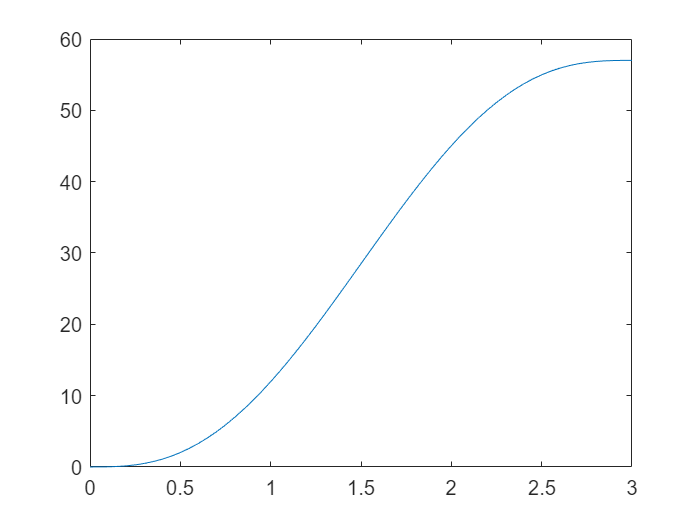

plot(t,path(:,3))

% we get the Discrete Position Velocity Acceleration

for i = 1:length(t)-1
    % delta_theta1(degree)
    path(i,1) = path(i+1,1)-path(i,1);
    % delta_theta3(degree)
    path(i,3) = path(i+1,3)-path(i,3);
    % delta_d4(mm)
    path(i,5) = path(i+1,5)-path(i,5);
end
path(end,1) = 0;
path(end,2) = 0;
path(end,3) = 0;
path(end,4) = 0;
path(end,5) = 0;
path(:,1)

ans =    -0.0010
   -0.0066
   -0.0174
   -0.0327
   -0.0521
   -0.0749
   -0.1008
   -0.1291
   -0.1596
   -0.1916


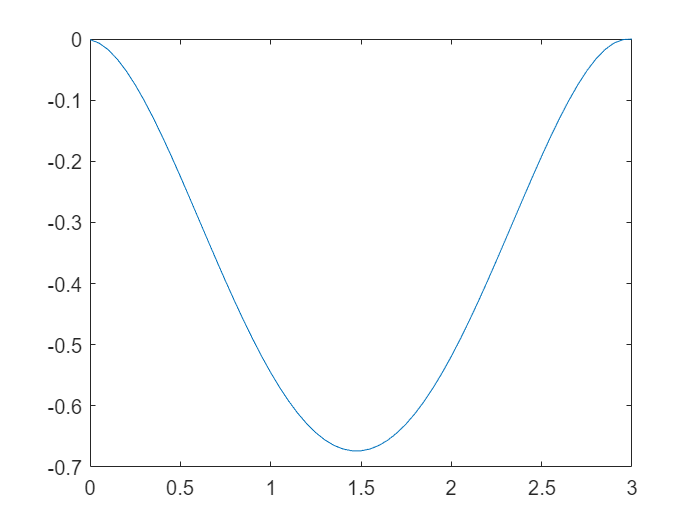

plot(t,path(:, 1))

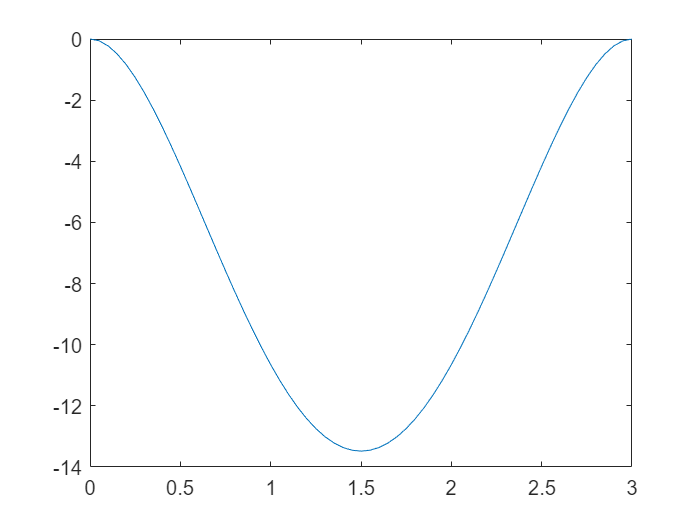

plot(t,path(:,2))

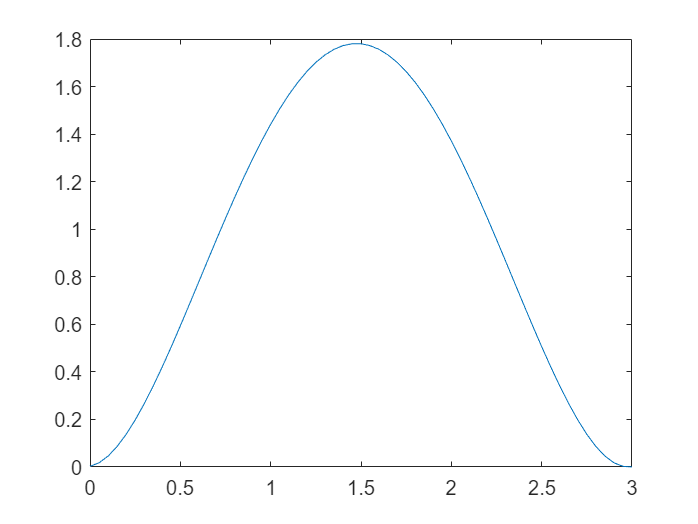

plot(t,path(:,3))

sum(path(:,1))

ans = -21.5727

sum(path(:,3))

ans = 57.0064